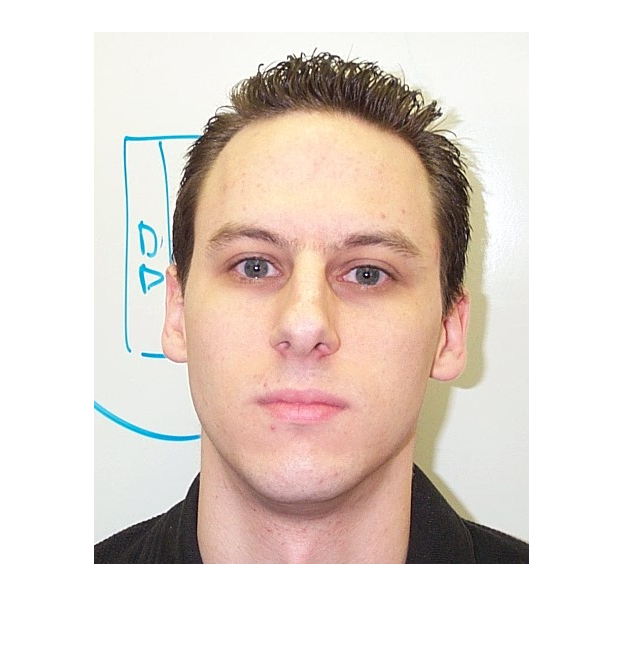

clear
img = (imread("a.png"));
images = loadFiles(dir("DB1/*.jpg"));

m = [110.3, 142.5];
C = [130.16, 10.15; 11.07, 280.35];

image = cell2mat(images(1,15));
imshow(image);

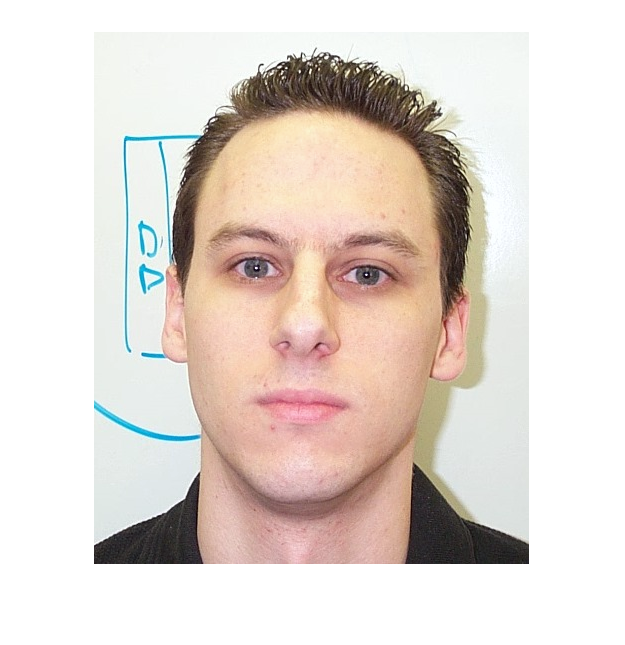


imageW = whitePoint(image);
imshow(imageW);

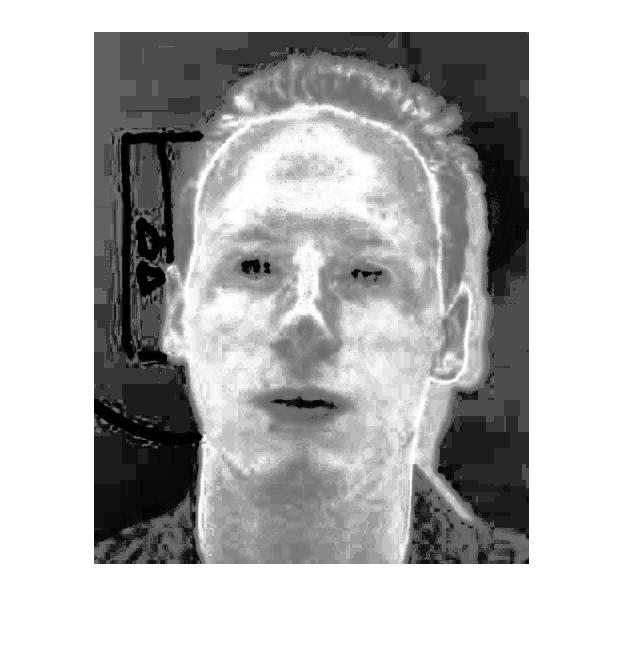


imageG =(gaussian(imageW, m, C));
imshow(imageG);

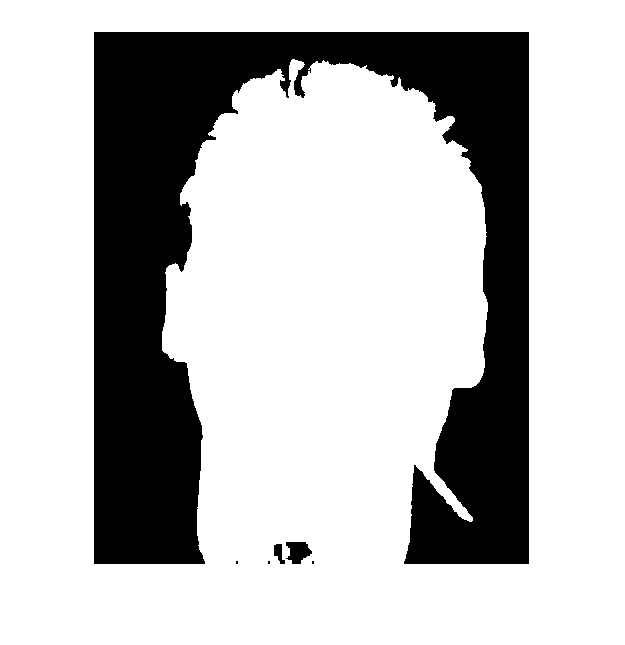


mask = skinMask(imageG);

imshow(mask);

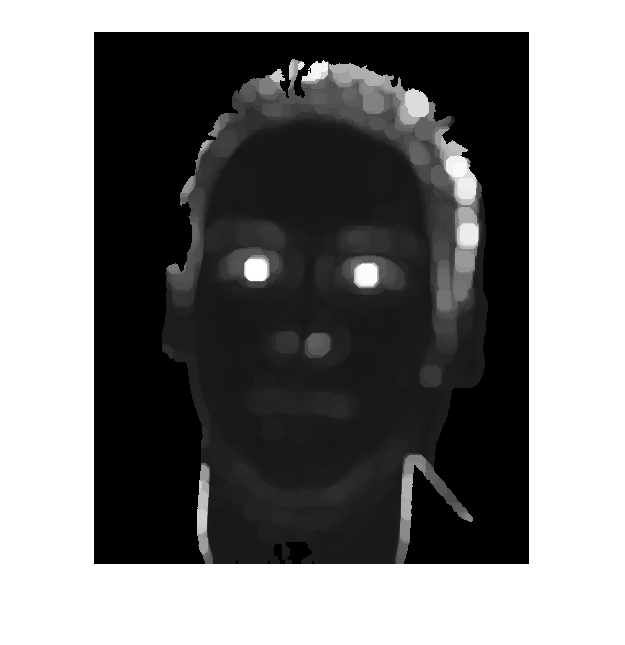


eyeMapped = eyemap(imageW, mask);
imshow(eyeMapped);


eyes = findEyes(eyeMapped);

stats =   207.4878   34.1707    1.0915
  272.6194  243.6000    1.0392
  162.8354  238.4654    1.0292
  374.2353  204.5416    1.0264
  323.3673   71.9727    0.9749
  313.9369  456.7573    0.8600
  184.0645   44.8145    0.7052
  197.9600   37.9733    0.6541
  282.7059   43.5098    0.5833
  223.5620   40.2680    0.5395


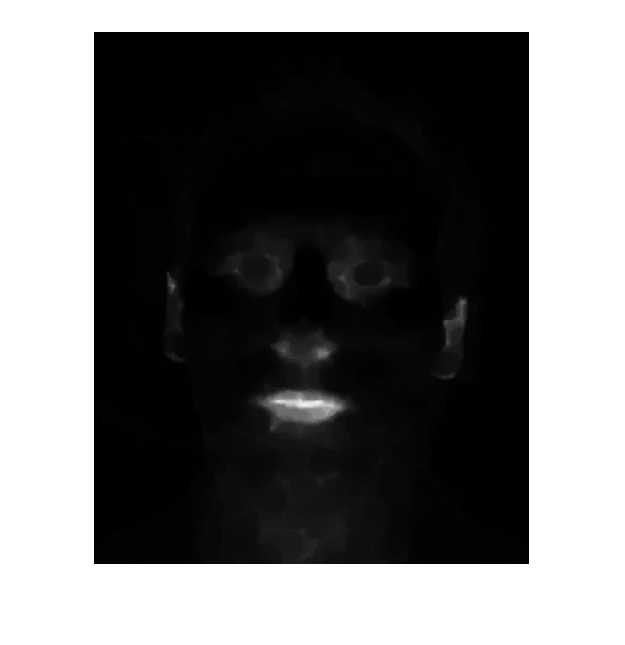


mouthMapped = mouthmap(image);
imshow(mouthMapped)

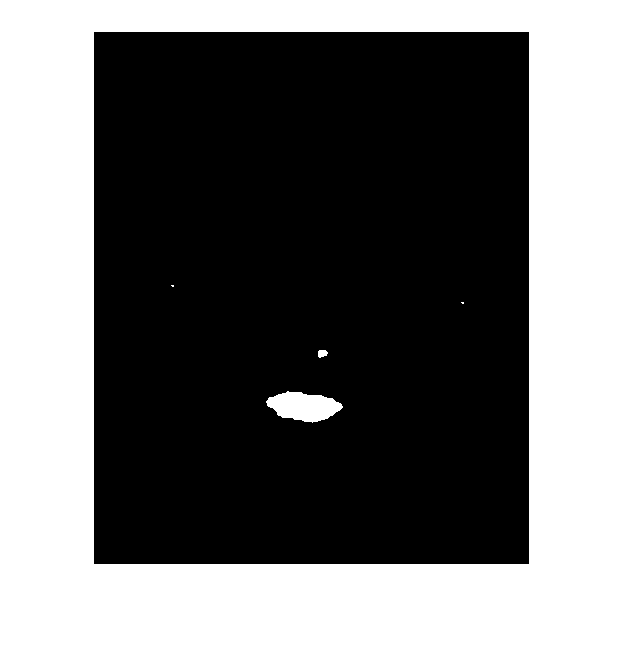


mouth = findMouth(mouthMapped);

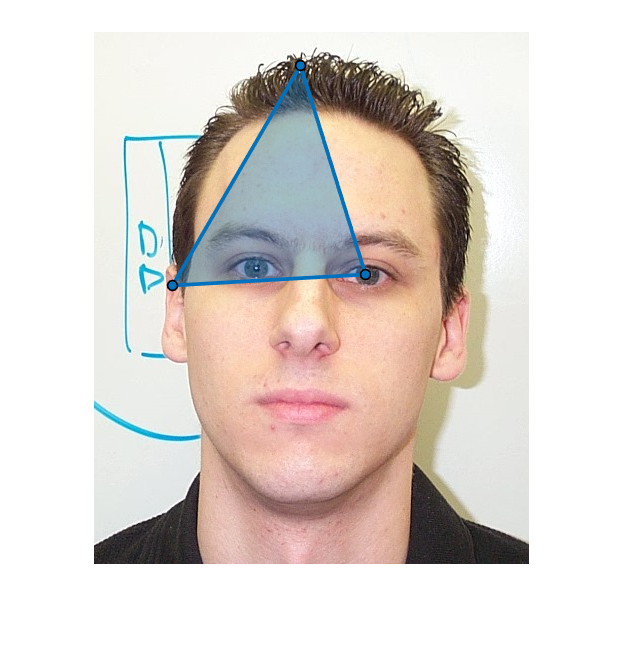


triangle = drawTriangle(eyes, mouth, image);